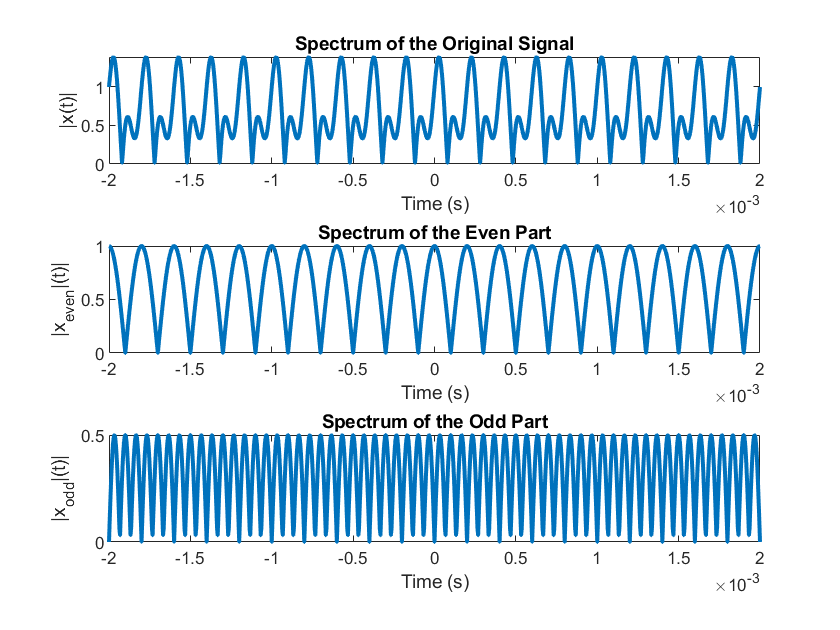

% Parameters
fs = 1000;  % Sampling frequency
T = 1/fs;   % Sampling period
t = 0:T:1;  % Time vector

% Real Signal (Combination of sinusoids)
f1 = 10;
f2 = 30;
x = cos(2*pi*f1*t) + 0.5*sin(2*pi*f2*t);

% Calculate even and odd parts
x_even = 0.5*(x + flip(x));  % Even part
x_odd = 0.5*(x - flip(x));   % Odd part

% Fourier Transforms
%X = fftshift(fft(x));
%X_even = fftshift(fft(x_even));
%X_odd = fftshift(fft(x_odd));

% Frequency axis
Times = linspace(-1/(fs/2), 1/(fs/2), length(t));

% Plot the spectrum of the original signal, even part, and odd part
figure;

subplot(3, 1, 1);
plot(Times, abs(x), 'LineWidth', 2);
title('Spectrum of the Original Signal');
xlabel('Time (s)');
ylabel('|x(t)|');

subplot(3, 1, 2);
plot(Times, abs(x_even), 'LineWidth', 2);
title('Spectrum of the Even Part');
xlabel('Time (s)');
ylabel('|x_{even}|(t)|');

subplot(3, 1, 3);
plot(Times, abs(x_odd), 'LineWidth', 2);
title('Spectrum of the Odd Part');
xlabel('Time (s)');
ylabel('|x_{odd}|(t)|');